% menngunakan data 13.5
sym s

$$ans = s$$

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



yss=1.887

yss = 1.8870

x=1.5

x = 1.5000

K=yss/x

K = 1.2580


t10 = 0.16

t10 = 0.1600

t30 = 0.28

t30 = 0.2800

t33 = 0.315

t33 = 0.3150

t50 = 0.51

t50 = 0.5100

t63 = 0.76

t63 = 0.7600

t70 = 0.95

t70 = 0.9500

t90 = 1.59

t90 = 1.5900

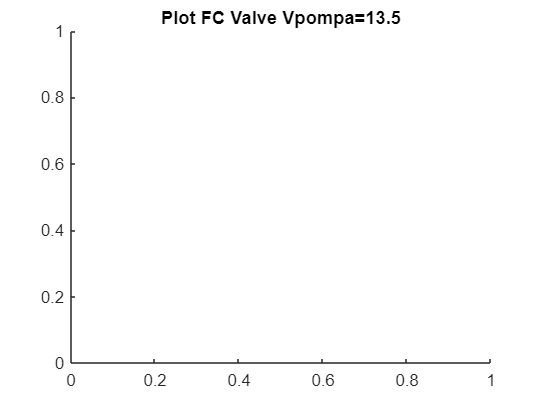

% ziegler time delay
% inflection point di 0.45
% persamaan garis y = 2.08x – 0.05
figure, title("Plot FC Valve Vpompa=13.5");
hold on;

waktu_datasets = (timestamp_13p5Vfc(54:154)-3052) / 1000;
flow_datasets = ltpmin_13p5Vfc(54:154);

figure, title("Datasets");
xlabel("waktu (detik)"); ylabel("flow (lt/min)"); hold on
plot(waktu_datasets,flow_datasets,"DisplayName","Datasets Vfc=13.5V")

Unrecognized function or variable 'waktu1'.

legend; hold off

selisih_waktu_PGL = timestamp_13p5Vfc(154) - timestamp_13p5Vfc(54); % linspace(0,2,2/0.05)

% cari data ke-k dimana terjadi inflection point, terjadi di awal kurva
% naik. Mendekati waktu = 0;    
y = diff(diff(flow_datasets));
figure, title("Turunan ke-2");
xlabel("waktu (detik)"); ylabel("flow (lt/min^2)"); hold on
plot(waktu_datasets(1:length(waktu_datasets)-2),flow_diff2,"DisplayName","2nd derivative when Vfc=13.5V")
legend; hold off



L = 

L_plusT = 
pers = 5.917806865597* selisih_waktu_PGL- 1.7764130895187
persc=pers(pers<=yss)
plot(waktugaris(1:length(persc)+2),pers(1:length(persc)+2),"DisplayName","garis singgung")
plot(linspace(0,5,500), ones(500,1)*yss)
plot(linspace(0,5,500), zeros(500,1))
hold off;
%sehingga diperoleh
L = 0.3
T = 0.621-L
zieg=K*exp(-L*s)/(T*s+1)
figure, title("Plot zieg");
hold on;
plot(waktu1,flow,"DisplayName","Datasets Vfc=13.5V")
plot(waktu1,yzieg,"DisplayName","garis singgung")


opt = stepDataOptions('InputOffset',0,'StepAmplitude',1.5);
[yzieg,waktu1]=step(zieg,waktu1,opt)
figure, title("Plot FC Valve Vpompa=13.5");
hold on;
xlabel("waktu");
ylabel("Flow rate (lt/min)")
plot(waktu1,flow,"DisplayName","Datasets Vfc=13.5V")
plot(waktu1,yvit1,"DisplayName","vit1")
plot(waktu1,yzieg,"DisplayName","latzel")
% plot(waktu1,lat,"DisplayName","vit2")
legend('dataset','vit1','ziegler','Location','SouthEast')
hold off